# My super notebook 

## Sliders with data

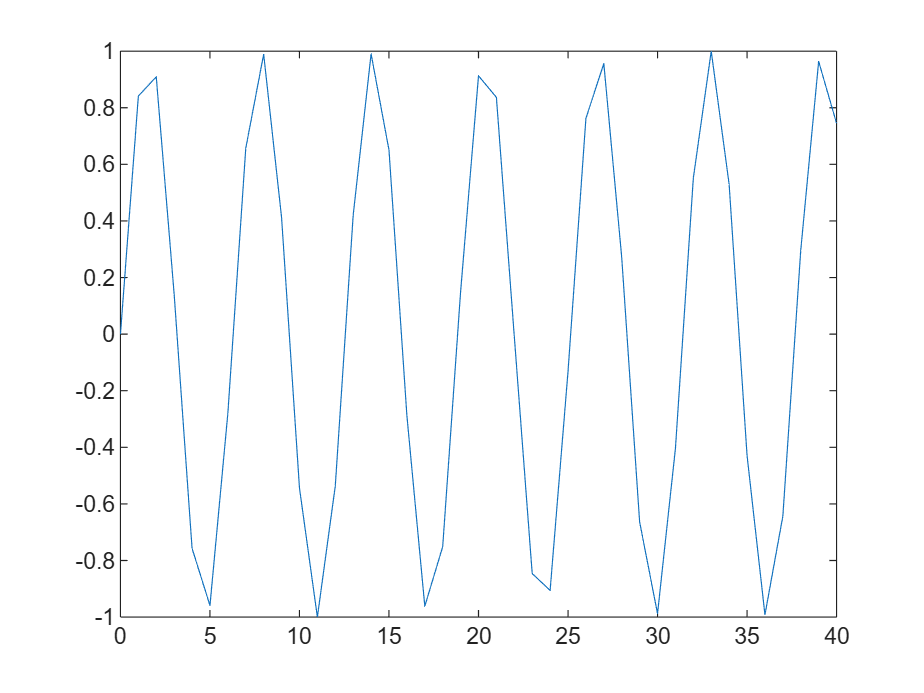

x = 0:1:40;
y = sin(x);
plot(x,y)

## Data generation

prompt: generate a weather dataset and store in a table

% Define the weather data
dates = datetime(2023,10,1) + days(0:9); % 10 days of data
temperatures = [20.5; 21.0; 19.8; 22.1; 23.5; 24.0; 22.8; 21.5; 20.0; 19.5]; % Temperatures in Celsius
precipitation = [0; 0; 5; 0; 0; 10; 0; 0; 0; 2]; % Precipitation in mm

% Create a table
weatherData = table(dates', temperatures, precipitation, ...
    'VariableNames', {'Date', 'Temperature_C', 'Precipitation_mm'})

weatherData = 10×3 table
       Date        Temperature_C    Precipitation_mm
    ___________    _____________    ________________

    01-Oct-2023        20.5                 0       
    02-Oct-2023          21                 0       
    03-Oct-2023        19.8                 5       
    04-Oct-2023        22.1                 0       
    05-Oct-2023        23.5                 0       
    06-Oct-2023          24                10       
    07-Oct-2023        22.8                 0       
    08-Oct-2023        21.5                 0       
    09-Oct-2023          20                 0       
    10-Oct-2023        19.5                 2       


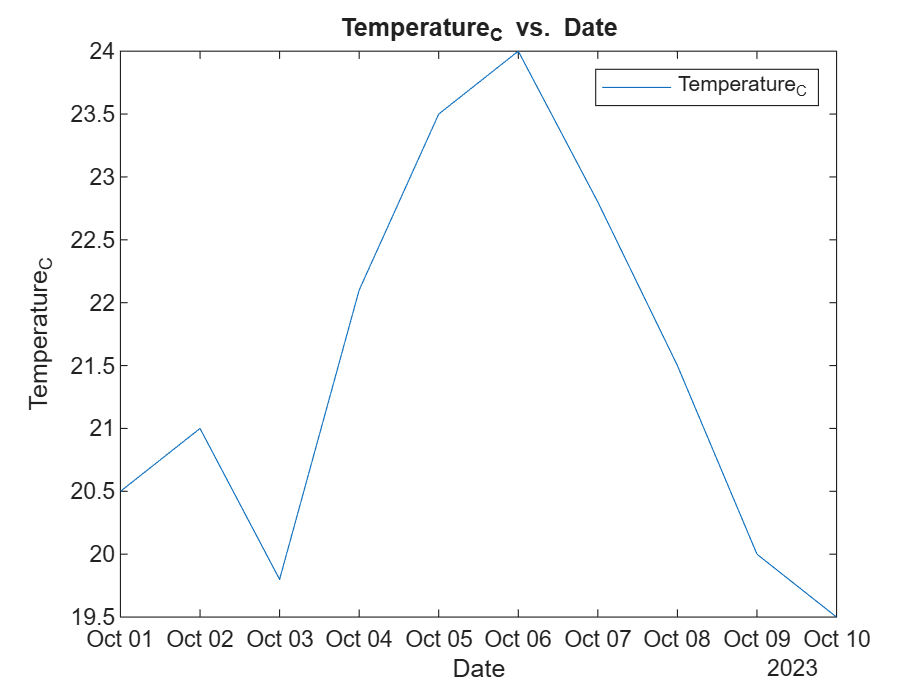

% Create plot of selected data
h = plot(weatherData,"Date","Temperature_C","DisplayName","Temperature_C");

% Add xlabel, ylabel, title, and legend
xlabel("Date")
ylabel("Temperature_C")
title("Temperature_C vs. Date")
legend

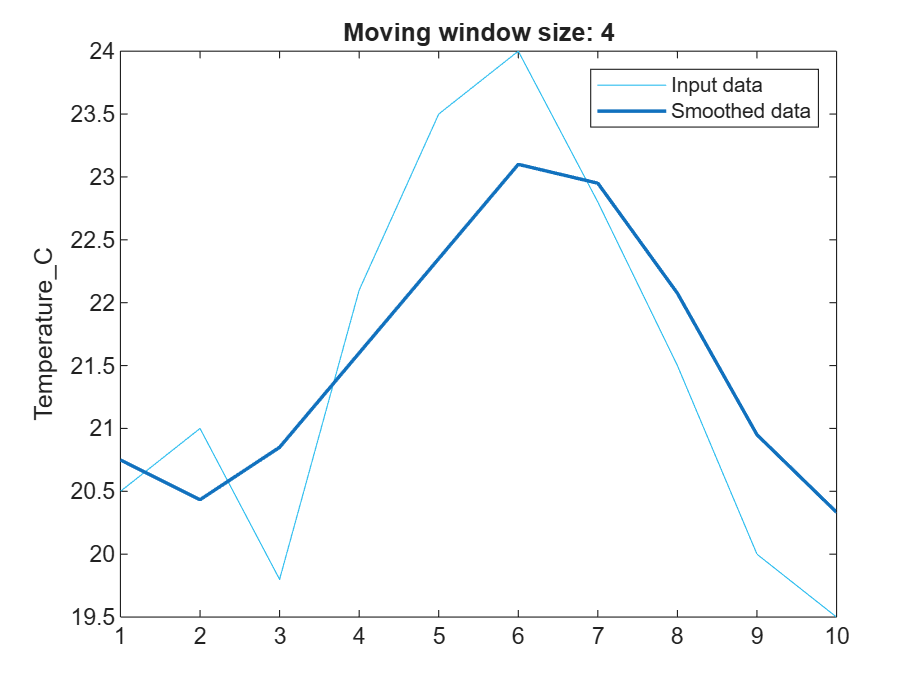

% Smooth input data
[newTable,winSize] = smoothdata(weatherData,"movmean",SmoothingFactor=0.25, ...
    DataVariables="Temperature_C");

% Display results
figure
plot(weatherData.Temperature_C,SeriesIndex=6,DisplayName="Input data")
hold on
plot(newTable.Temperature_C,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Temperature_C",Interpreter="none")

clear winSize
